## Bisection method

Plot the function:

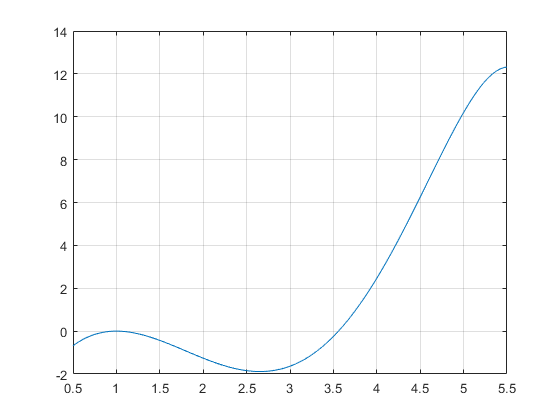

close all;
clc;

f = @(x) x.^3 - (2 + exp(1)).*x.^2 + (2*exp(1) + 1).*x + (1 - exp(1)) - cosh(x - 1);

a = 0.5;
b = 5.5;

x = linspace(a, b, 1000);

figure();
plot(x, f(x));
grid on;

Call bisection with the considered domain [3, 5]:

a = 3;
b = 5;
tol = 1e-3;

[x, iter] = bisection(f, a, b, tol);


display(x);

x = 3.5581

display(iter);

iter =     4.0000    3.5000    3.7500    3.6250    3.5625    3.5313    3.5469    3.5547    3.5586    3.5566    3.5576    3.5581


Function:

function [x, x_iter] = bisection(f, a, b, tol, x_iter)
    Nmax = ceil(log((b-a/tol))/log(2));
    
    for i = 1:Nmax
        x_iter(i) = (b+a)/2;
        
        if f(x_iter(i))*f(a) < 0
            b = x_iter(i);
        else
            a = x_iter(i);
        end
    end
    
    x = x_iter(end);
end